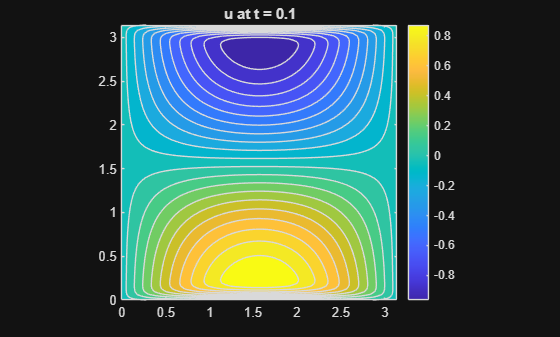

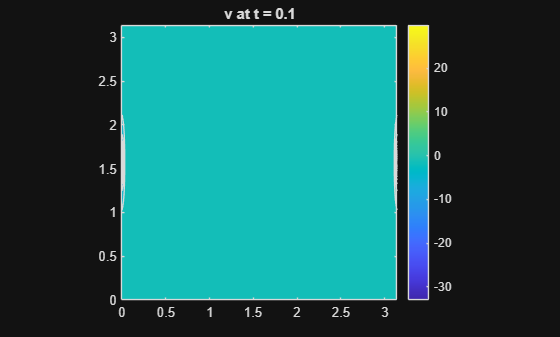

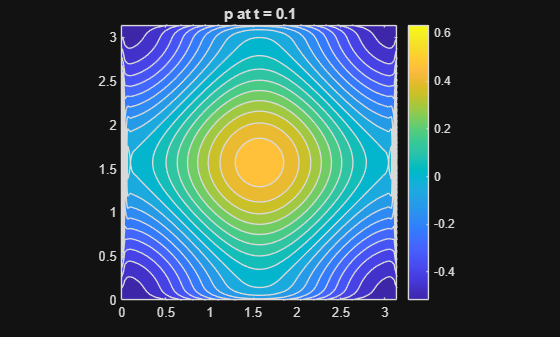

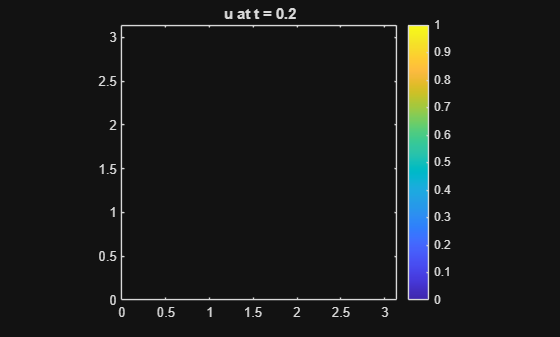

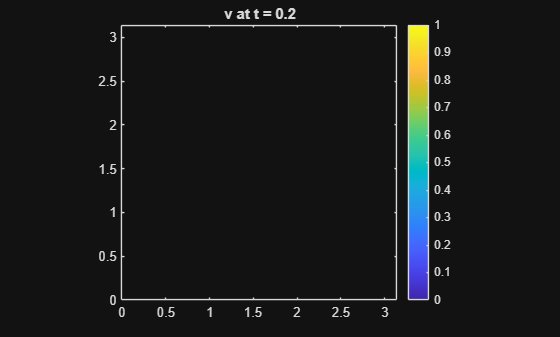

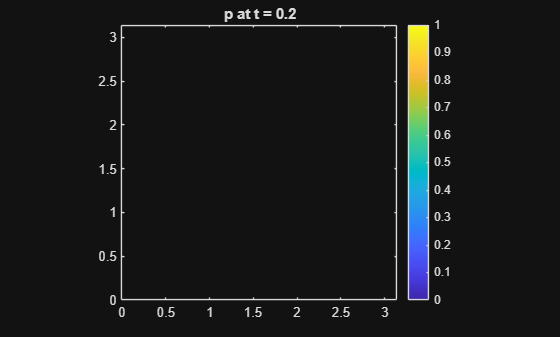

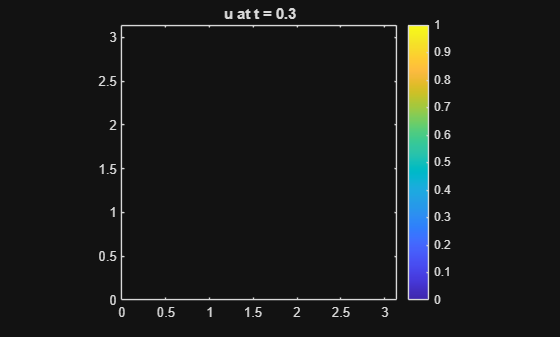

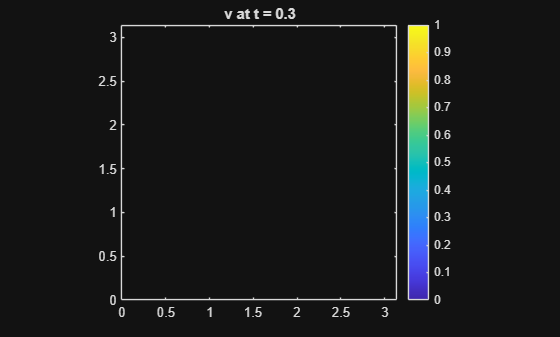

% =========================================================================
%    MATLAB: Taylor–Green Vortex 2D – Implementación con CC Periódicas
% =========================================================================

%% 0. Parámetros físicos y numéricos
Lx = pi;  Ly = pi;             
Nx = 100; Ny = 100;            
dx = Lx/(Nx-1); dy = Ly/(Ny-1);
dt = 0.001;                    
nu = 1e-2;                     
beta = 1e1;                    
Nt = 500;                      

% Coordenadas
x = linspace(0,Lx,Nx);
y = linspace(0,Ly,Ny);
[X,Y] = meshgrid(x,y);

%% 1. Condiciones iniciales (analítica)
u =  sin(X).*cos(Y);
v = -cos(X).*sin(Y);
p = -(cos(2*X)+cos(2*Y))/4;

u_vec = reshape(u,[],1);
v_vec = reshape(v,[],1);
p_vec = reshape(p,[],1);

%% 2. Operadores dispersos con CC periódicas
% Construimos matrices circulantes para primera y segunda derivada
e = ones(Nx,1);
% Periodic 1D Laplacian
L1D = spdiags([e -2*e e], -1:1, Nx, Nx);
L1D(1,Nx) = 1;   L1D(Nx,1) = 1;   % periodic wrap
L1D = L1D / dx^2;
% Periodic 1D first derivative (central)
D1 = spdiags([-e zeros(Nx,1) e], -1:1, Nx, Nx) / (2*dx);
D1(1,Nx) = -1/(2*dx);  D1(Nx,1) = 1/(2*dx);

% Ahora el 2D por Kronecker
Ix = speye(Nx); Iy = speye(Ny);
Lx2 = kron(Iy, L1D);
Ly2 = kron(L1D, Ix);
L  = Lx2 + Ly2;             % Laplaciano 2D periódico
A  = speye(Nx*Ny) - nu*dt*L;

Dx = kron(Iy, D1);
Dy = kron(D1, Ix);

%% 3. Bucle de tiempo corregido
for n = 1:Nt
  % Extraer
  u_old = u_vec;  v_old = v_vec;  p_old = p_vec;

  % Advección
  adv_u = u_old .* (Dx*u_old) + v_old .* (Dy*u_old);
  adv_v = u_old .* (Dx*v_old) + v_old .* (Dy*v_old);

  % Gradiente de presión
  gradpx = Dx * p_old;
  gradpy = Dy * p_old;

  % RHS momentums
  RHSu = u_old + dt*(-adv_u - gradpx);
  RHSv = v_old + dt*(-adv_v - gradpy);

  % Difusión implícita
  u_star = A \ RHSu;
  v_star = A \ RHSv;

  % Continuidad (compresibilidad artificial)
  div_star = Dx*u_star + Dy*v_star;
  p_new = p_old - (dt/beta)*div_star;

  % Corrección de velocidades
  u_vec = u_star - (dt/beta)*(Dx*(p_new-p_old));
  v_vec = v_star - (dt/beta)*(Dy*(p_new-p_old));
  p_vec = p_new;

  % Visualización cada 100 pasos en gráficas separadas
  if mod(n,100)==0
    U = reshape(u_vec,Ny,Nx);
    V = reshape(v_vec,Ny,Nx);
    P = reshape(p_vec,Ny,Nx);

    figure; contourf(X,Y,U,20); 
      title(['u at t = ' num2str(n*dt)]); axis equal tight; colorbar;

    figure; contourf(X,Y,V,20); 
      title(['v at t = ' num2str(n*dt)]); axis equal tight; colorbar;

    figure; contourf(X,Y,P,20); 
      title(['p at t = ' num2str(n*dt)]); axis equal tight; colorbar;

    drawnow;
  end
end